# RX Anomaly score on Reflection

## First we try calculating the scores on the whole image



regionPixels = find(labelscyto > 0);
R = Reflection;
for i = (1:13)
    R(:,:,i) = wiener2(R(:,:,i),[5 5]); % apply denoising to the bands
end

%scores with denoising
rxScoresprep = anomalyRX(R); 

%scores without denoising
rxScores = anomalyRX(Reflection);

rxScores = im2uint8(rescale(rxScores));
rxScoresprep = im2uint8(rescale(rxScoresprep));

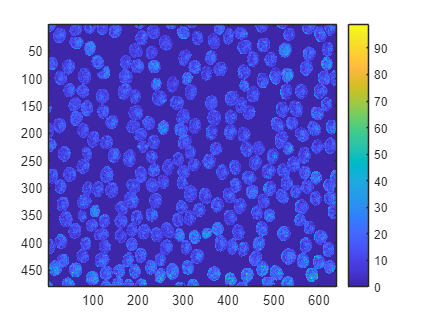

% set up a masked version that only shows values wihtin cells
masked = rxScores;
masked(labelscyto == 0) = 0;
maskedp = rxScoresprep;
maskedp(labelscyto == 0) = 0;
imagesc(masked)
colorbar

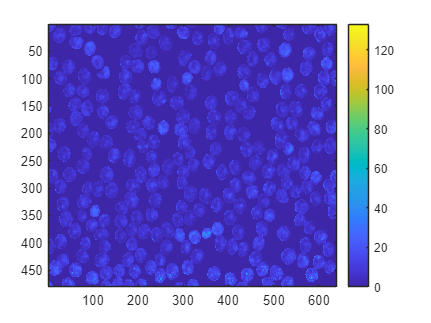

imagesc(maskedp) %with denoising, results seem better
colorbar

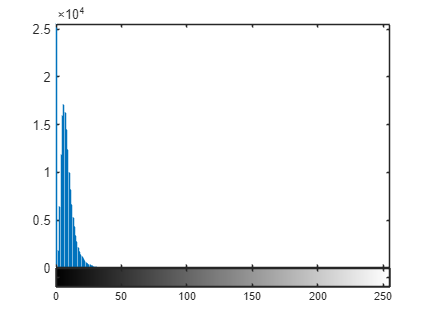

imhist(maskedp)

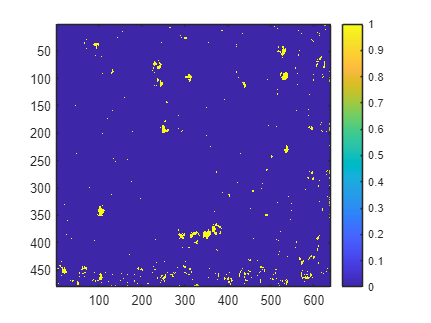

thresh= maskedp > 20;
thresh(thresh > 100) = 0;
imagesc(thresh)
colorbar

## Now we try to automate candidate selection

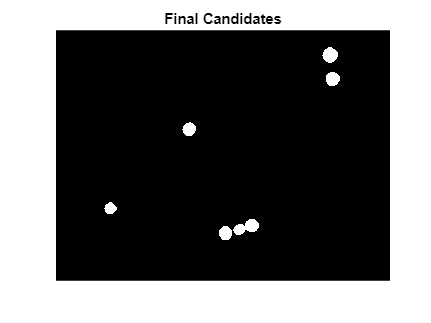


numLabels = max(labelscyto(:));

% Initialize a mask to hold the selected labels
selectedMask = zeros(size(labelscyto));

% Loop through each label
for label = 1:numLabels
    % Get a binary mask for the current label
    labelMask = (labelscyto == label);
    
    % Count the total number of pixels in this label
    totalPixels = sum(labelMask(:));
    
    % sum the score of anomalous pixels in this label
    numAnomalous = sum(thresh(labelMask));
    
    % Calculate the final score of anomalous pixels in this label
    anomalyPercentage = (numAnomalous / totalPixels) * 100;
    
    % If the anomaly score exceeds the threshold, keep this label
    if numAnomalous > 150
        selectedMask(labelMask) = label;
    end
end
imshow(selectedMask);
title('Final Candidates');

## Now we try to minimimize background pixels when calculating rxScore

% Get the dimensions of the hyperspectral image
[X, Y, Bands] = size(Reflection);

% Get the total number of labels in the segmentation mask
numLabels = max(labelscyto(:));

% Cap MaxPixelsPerLabel at 800
MaxPixelsPerLabel = min(800, ceil((X * Y) / numLabels));

% Initialize a 3D matrix to store the spectra
% Dimensions: [numLabels, MaxPixelsPerLabel, Bands]
spectraMatrix = zeros(numLabels, MaxPixelsPerLabel, Bands);

% Loop through each label
for label = 1:numLabels
    % Get a binary mask for the current label
    labelMask = (labelscyto == label);
    
    % Find the indices of the pixels in this label
    [row, col] = find(labelMask);
    
    % Limit the number of pixels to MaxPixelsPerLabel
    numPixels = min(length(row), MaxPixelsPerLabel);
    row = row(1:numPixels);
    col = col(1:numPixels);
    
    % Extract the spectra of these pixels
    pixelSpectra = zeros(numPixels, Bands); % Preallocate for spectra
    for i = 1:numPixels
        % Get the spectra for each pixel using row, col indices
        pixelSpectra(i, :) = R(row(i), col(i), :);
    end
    
    % Store the spectra in the 3D matrix
    spectraMatrix(label, 1:numPixels, :) = pixelSpectra;
end

% Display the dimensions of the resulting spectra matrix
disp(size(spectraMatrix));

   266   800    13



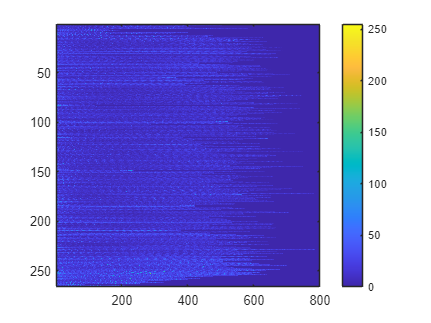

rxScores = anomalyRX(spectraMatrix);

rxScores = im2uint8(rescale(rxScores));
imagesc(rxScores)
colorbar

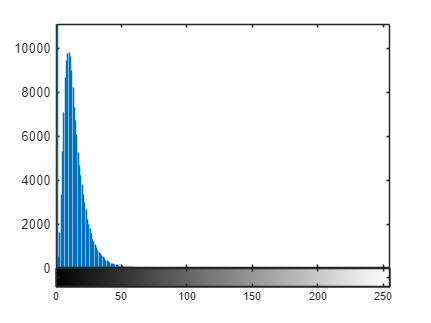


imhist(rxScores)

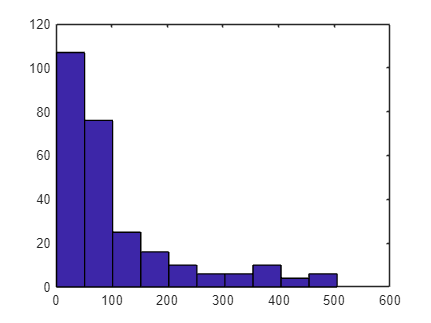

thresh = rxScores>20;

%Calculate the anomaly score of every cell
threshs = sum(thresh,2);
hist(threshs)

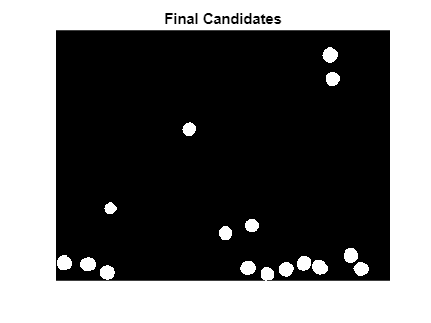


selectedMask = zeros(size(labelscyto));
%Loop through every score and discard below the threshold
for label = 1:numLabels
    labelMask = (labelscyto == label);
    if threshs(label) > 375  
        selectedMask(labelMask) = label;
    end
end
imshow(selectedMask);
title('Final Candidates');

%noisy cells are very favored even with denoising and a high threshold